%% Examples using Evaluate_Masks function (Nov-2024)

% without any parameter. This means Pause_Period = 0 and evaluates the
% masks stored in the directories selected by user interactivelly.

[Pre, Rec, FScore] = Evaluate_Masks;

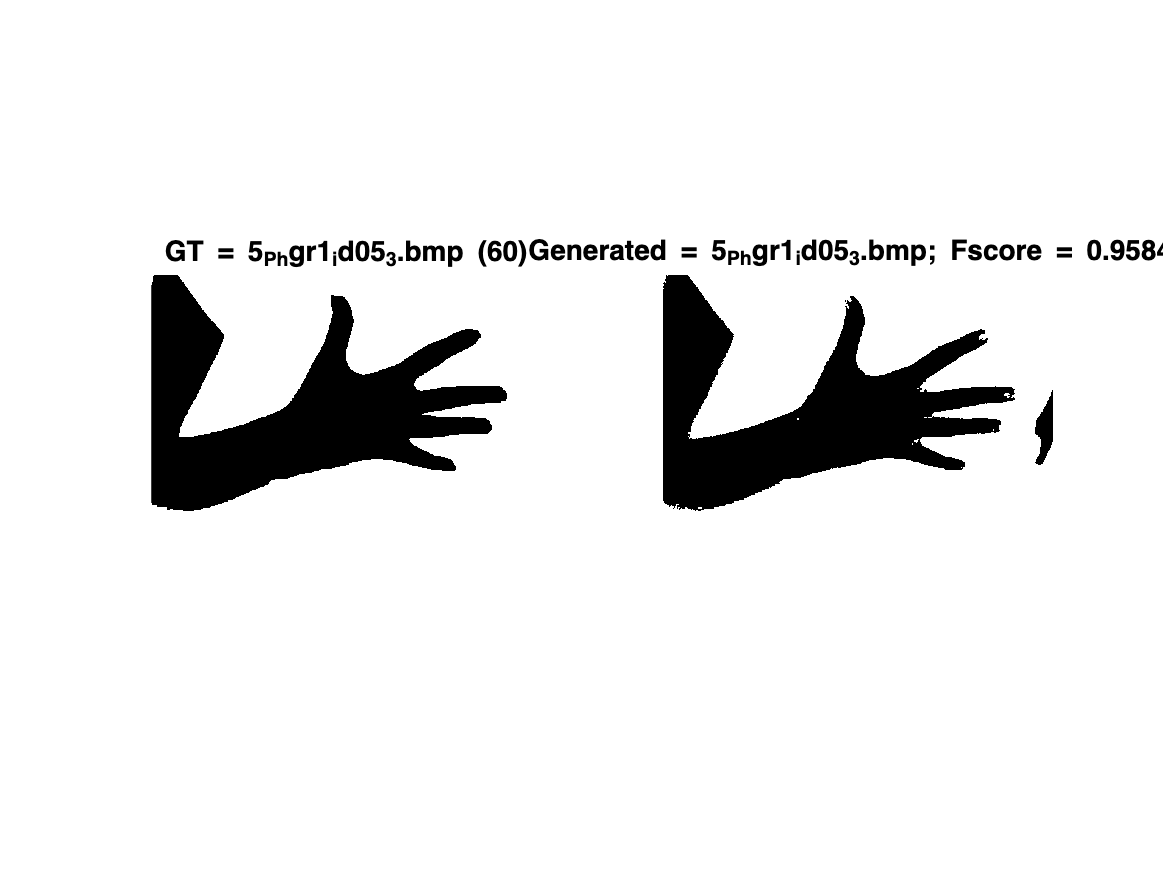

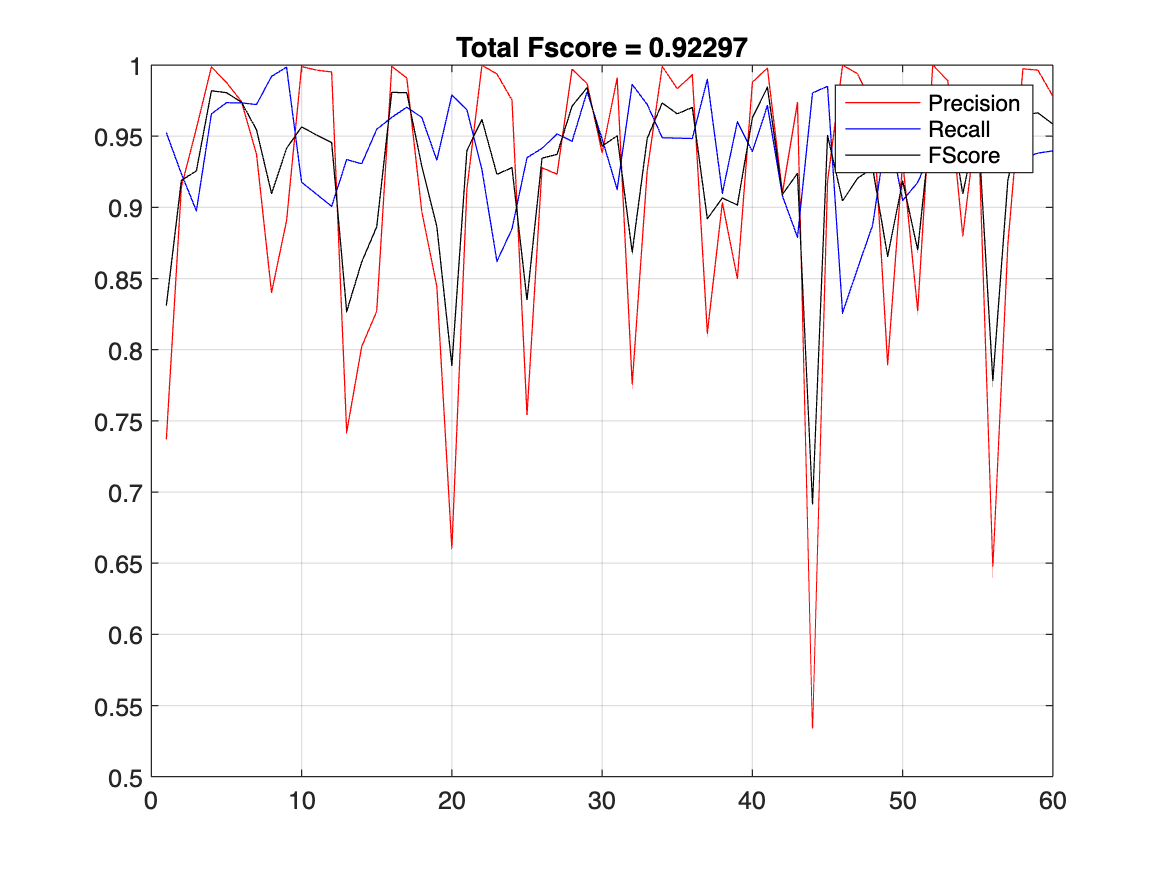

Mean Fscore = 0.92297


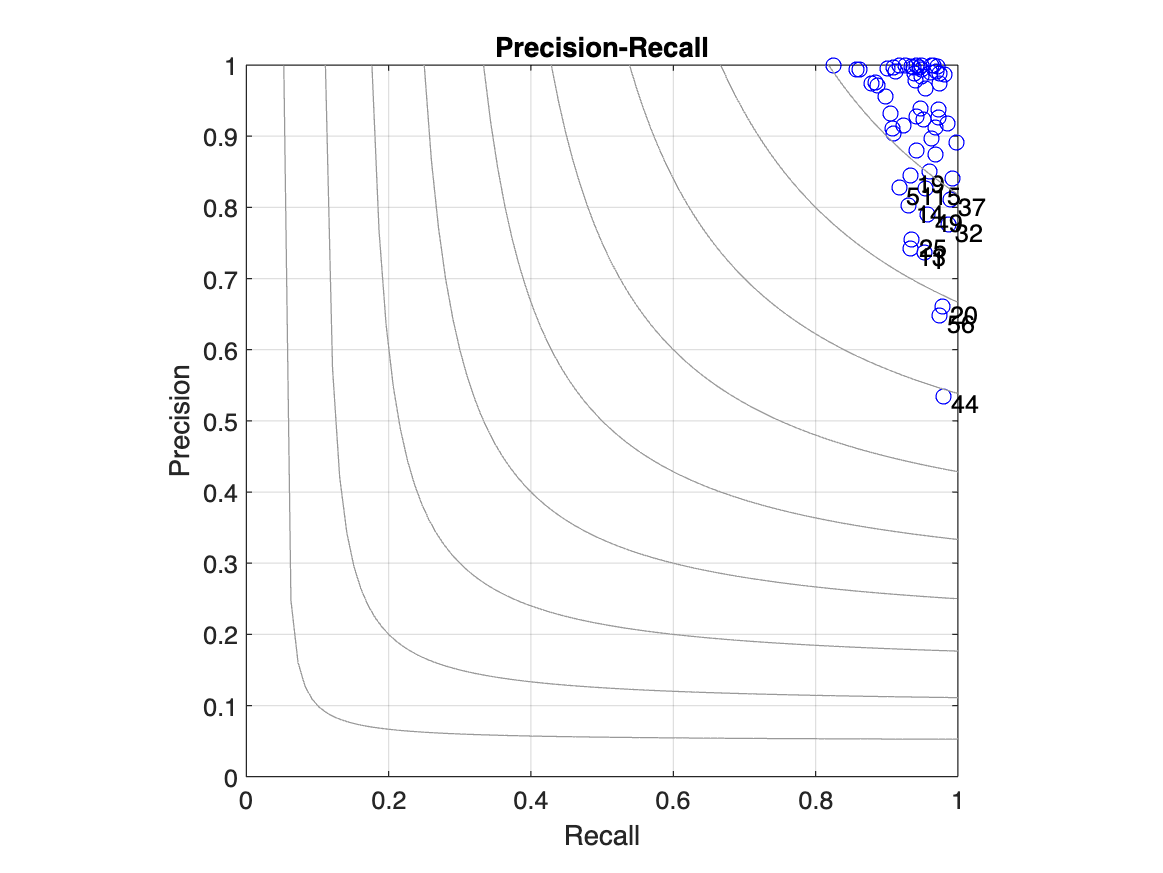

%% Alternativelly you can specify Pause_period and the corresponding directories:
% 
% For testing purpouse:
% [Pre,Rec,FScore] = Evaluate_Masks(0, './Training-Dataset/Masks-Ideal/', './Training-Dataset//Masks-Ideal/');

[Pre, Rec, FScore] = Evaluate_Masks(0, './Training-Dataset/Masks-Ideal/', './Training-Dataset/Masks/');

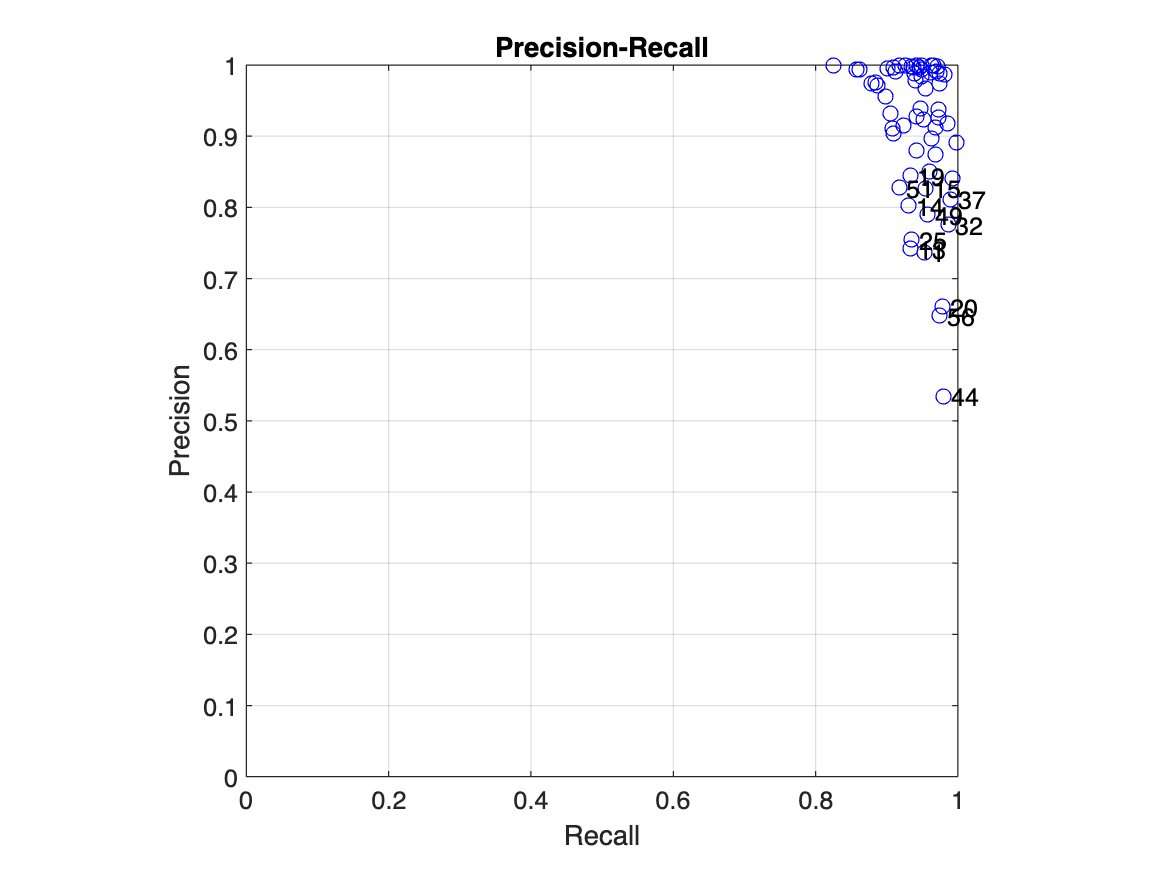

%% Example for ploting Precision/Recall results (vectors Pre, Rec & FScore)

figure(10)
plot(Rec,Pre,'ob');
grid
title('Precision-Recall');
ylabel('Precision')
xlabel('Recall')
axis equal
axis([0 1 0 1])

% Labeling the FScore values for results below Fvalue
Fvalue = 0.9;
hold on
for i=1:length(Pre)
    if (FScore(i)<Fvalue)
        text(Rec(i)+0.01,Pre(i),num2str(i));
    end
end
hold off